## Experimental Data - Heatmaps

**Author:** Surabhi Joshi

## Load Exper_data.mlx 

Start by loading exper_data.mlx to have all of the data tables for the parallel coordinate plots

exper_data;

## Correlation Matrix - Conditions

Start by converting any NaN values in the mean array into 0. Then create a correlation matrix of the conditions to plot. 

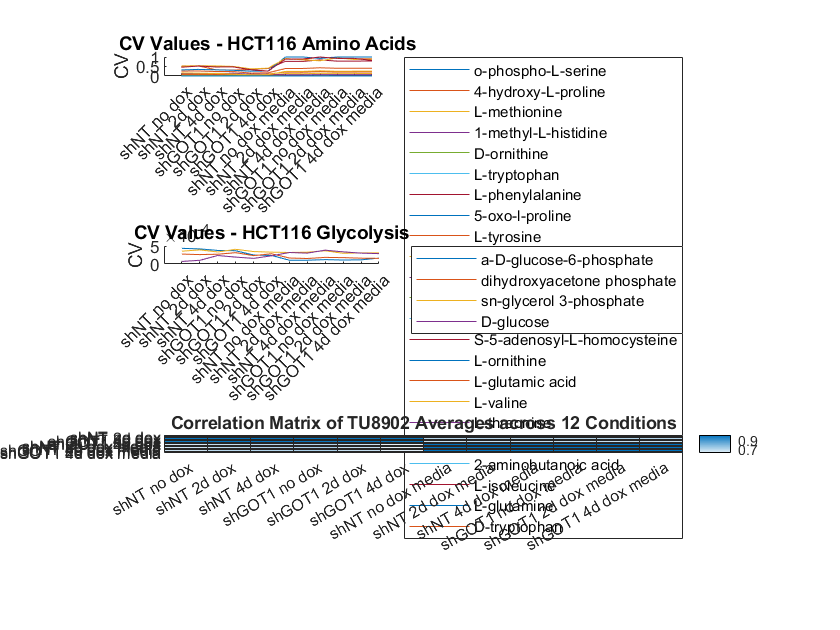

% Convert all the NaN values to 0
mean_metabolomic_array_TU8902(isnan(mean_metabolomic_array_TU8902)) = 0;
mean_metabolomic_array_HCT116(isnan(mean_metabolomic_array_HCT116)) = 0;

% R matrix and its heatmap - TU8902
averageCorrMat_TU8902 = corrcoef(mean_metabolomic_array_TU8902);
figure (1);
heatmap(all_conditions, all_conditions, averageCorrMat_TU8902);
title 'Correlation Matrix of TU8902 Averages across 12 Conditions';

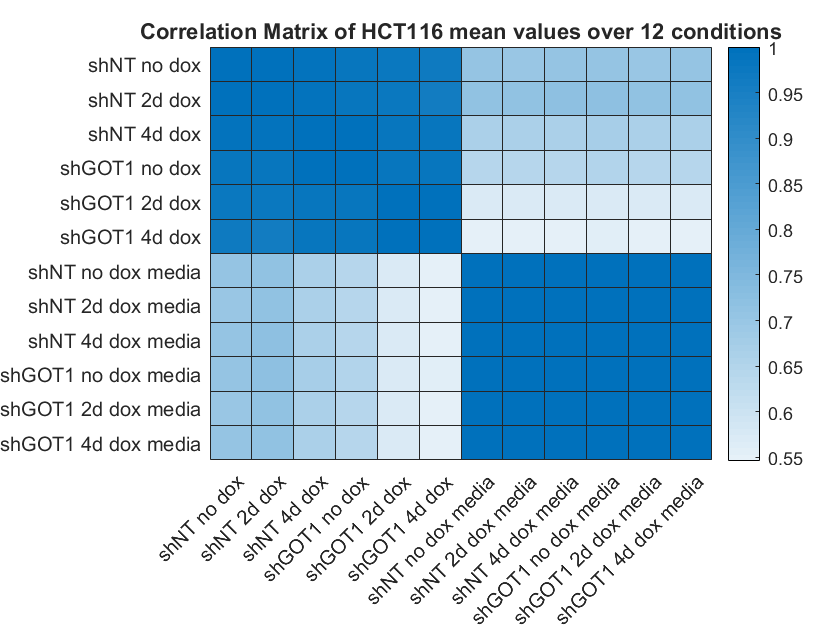


% R matrix and its heatmap - HCT116
averageCorrMat_HCT116 = corrcoef(mean_metabolomic_array_HCT116);
figure (2);
heatmap(all_conditions, all_conditions, averageCorrMat_HCT116);
title 'Correlation Matrix of HCT116 mean values over 12 conditions';

**Analysis:**

## Correlation Matrix - Metabololites

Repeat the above to create and plot a correlation matrix for the metabolites by first transposing the arrays

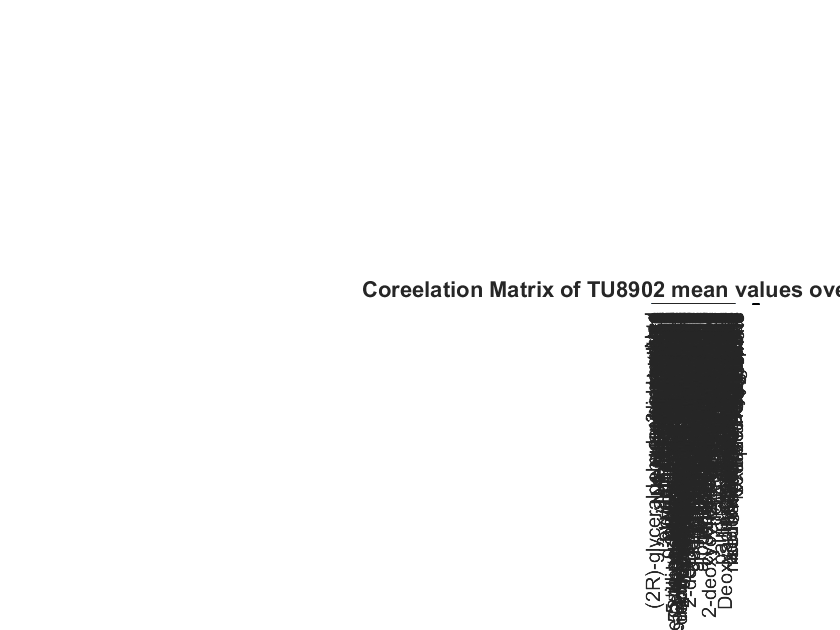

% TU8902
corrmat_metabolite_TU8902 = corr(mean_metabolomic_array_TU8902', mean_metabolomic_array_TU8902');
figure(3);
heatmap(metabolomics_TU8902(:,1),metabolomics_TU8902(:,1), corrmat_metabolite_TU8902);
title('Coreelation Matrix of TU8902 mean values over 224 Metabolites');

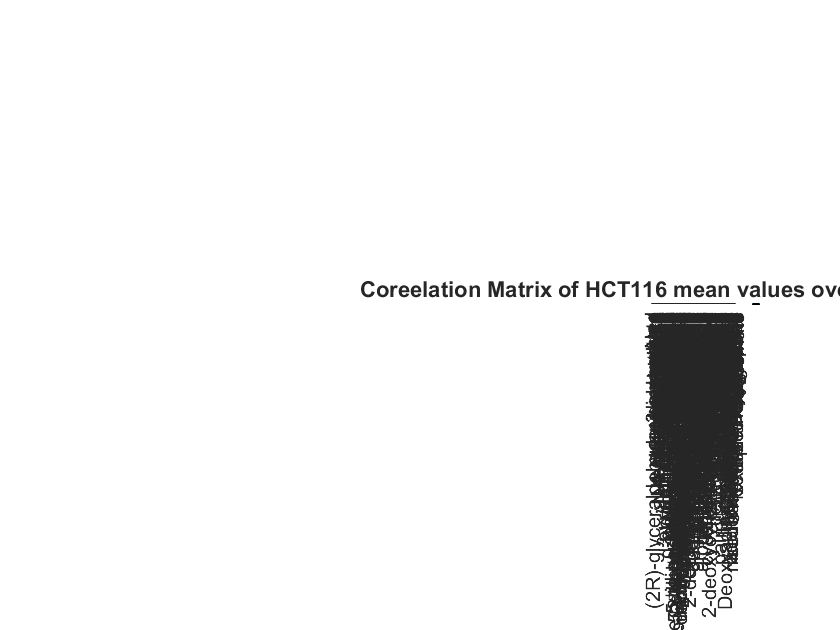


% HCT116
corrmat_metabolite_HCT116 = corr(mean_metabolomic_array_HCT116', mean_metabolomic_array_HCT116');
figure(4);
heatmap(metabolomics_HCT116(:,1),metabolomics_HCT116(:,1), corrmat_metabolite_HCT116);
title('Coreelation Matrix of HCT116 mean values over 224 Metabolites');

**Analysis:**

## Heatmap: Mean Unfiltered

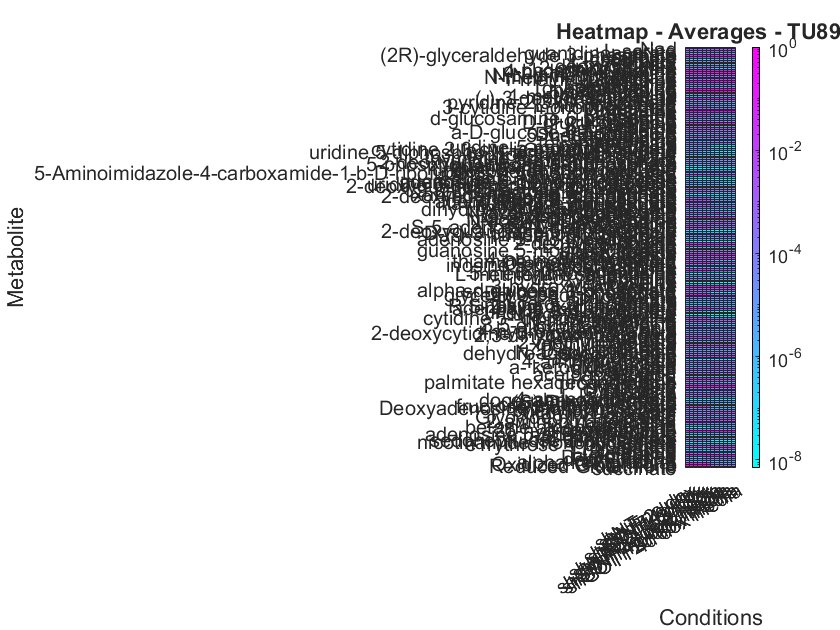

figure (5);
heatmap(all_conditions, metabolomics_TU8902(:,1),mean_metabolomic_array_TU8902, 'ColorScaling', 'log');
xlabel('Conditions');
ylabel('Metabolite');
title('Heatmap - Averages - TU8902');
colormap 'cool';

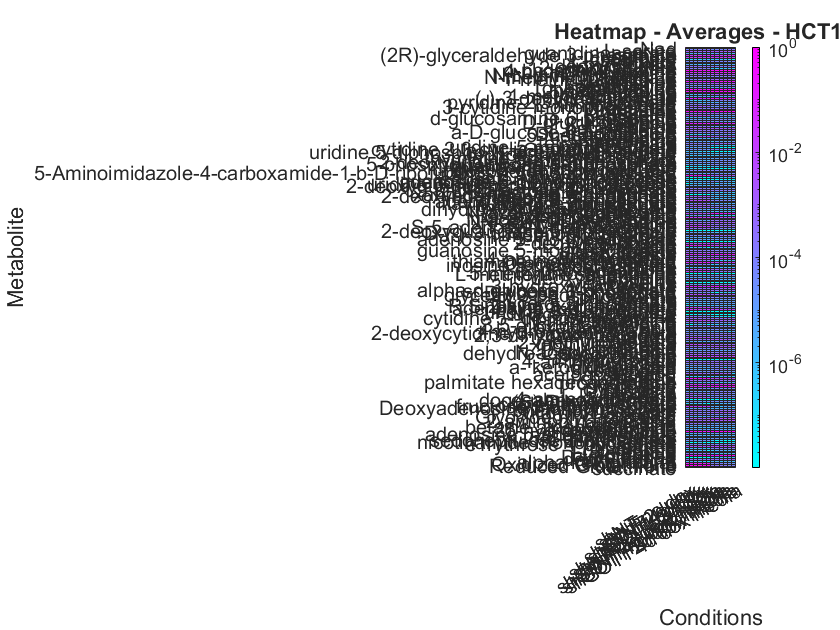


figure (6);
heatmap(all_conditions, metabolomics_HCT116(:,1),mean_metabolomic_array_HCT116, 'ColorScaling', 'log');
xlabel('Conditions');
ylabel('Metabolite');
title('Heatmap - Averages - HCT116');
colormap 'cool';

## Heatmap: CV Filtered,  CV = 0.1 + NaN

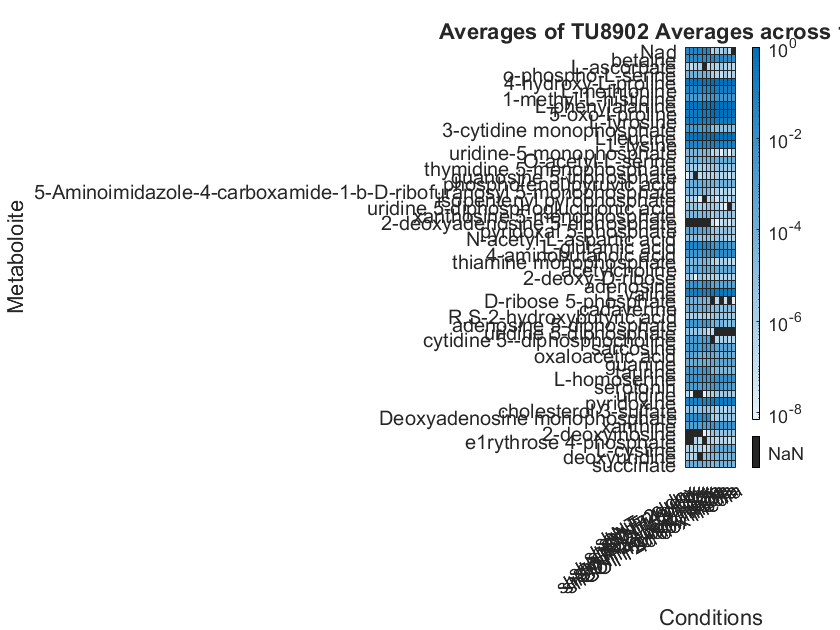

figure (9);
heatmap(all_conditions, metabolomics_TU8902_01(:,1),table2array(filtered_table_TU8902_01), 'ColorScaling', 'log');
title 'Averages of TU8902 Averages across 12 Conditions';
xlabel('Conditions');
ylabel('Metaboloite');

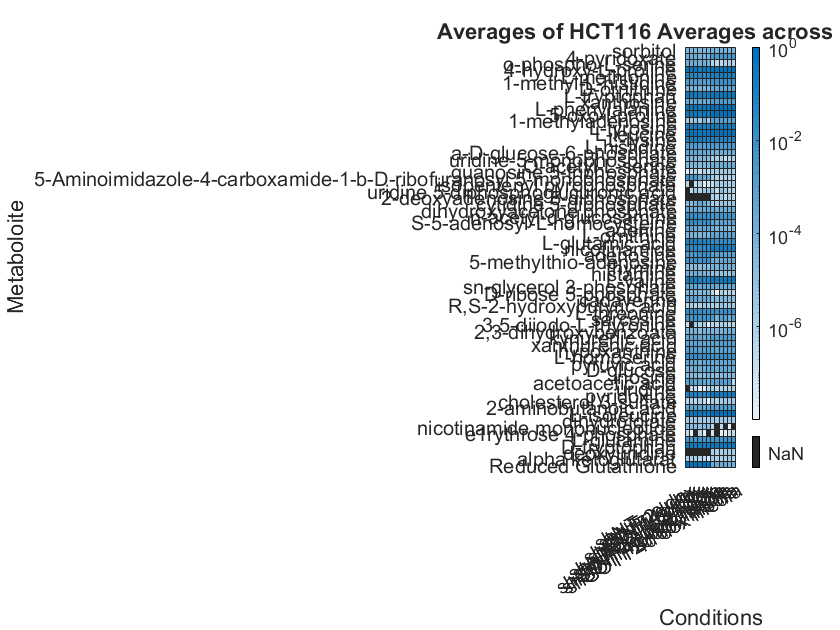


figure (10);
heatmap(all_conditions, metabolomics_HCT116_01(:,1),table2array(filtered_table_HCT116_01), 'ColorScaling', 'log');
title 'Averages of HCT116 Averages across 12 Conditions';
xlabel('Conditions');
ylabel('Metaboloite'); 

## Heatmap: CV Filtered, CV = 0.3 + NaN

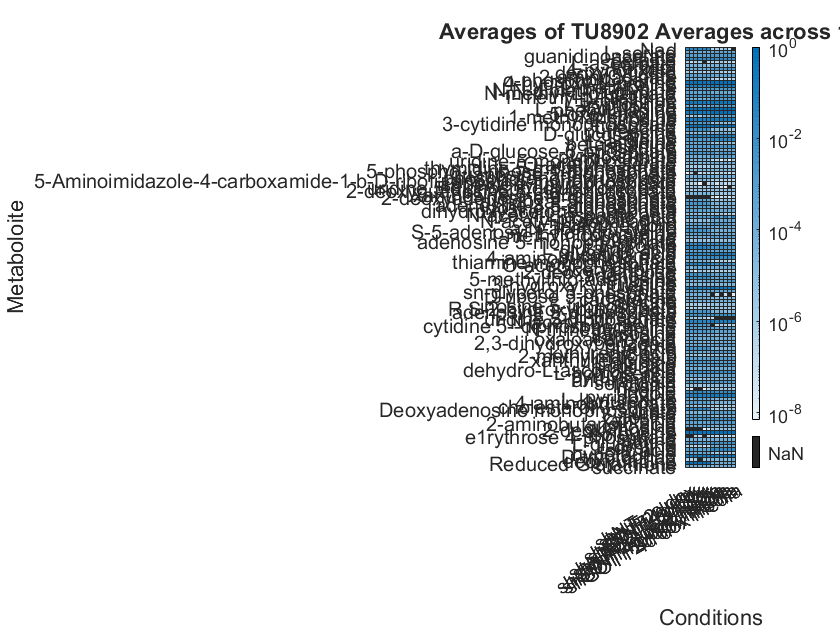

figure (13);
heatmap(all_conditions, metabolomics_TU8902_03(:,1),table2array(filtered_table_TU8902_03), 'ColorScaling', 'log');
title 'Averages of TU8902 Averages across 12 Conditions';
xlabel('Conditions');
ylabel('Metaboloite');

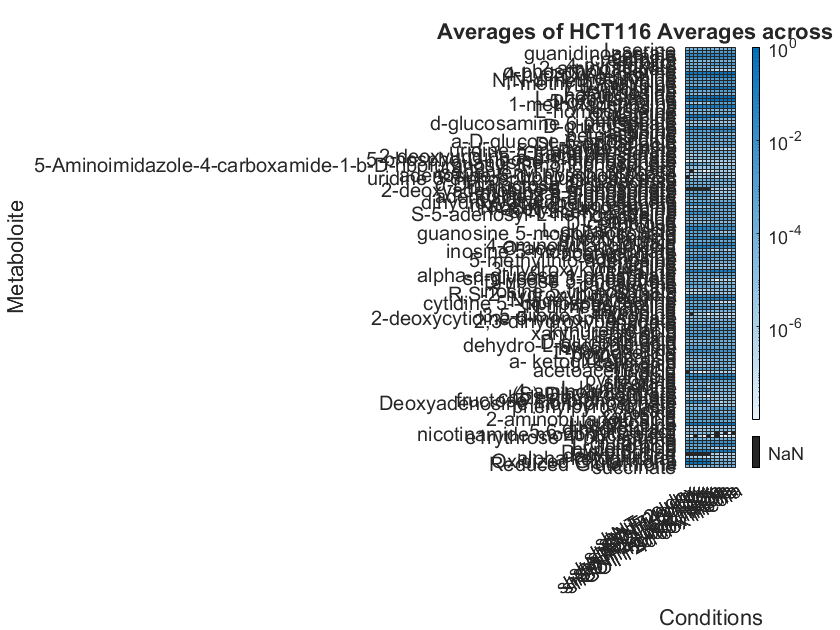


figure (14);
heatmap(all_conditions, metabolomics_HCT116_03(:,1),table2array(filtered_table_HCT116_03), 'ColorScaling', 'log');
title 'Averages of HCT116 Averages across 12 Conditions';
xlabel('Conditions');
ylabel('Metaboloite'); 

## Heatmap: CV Filtered, CV = 0.6 + NaN

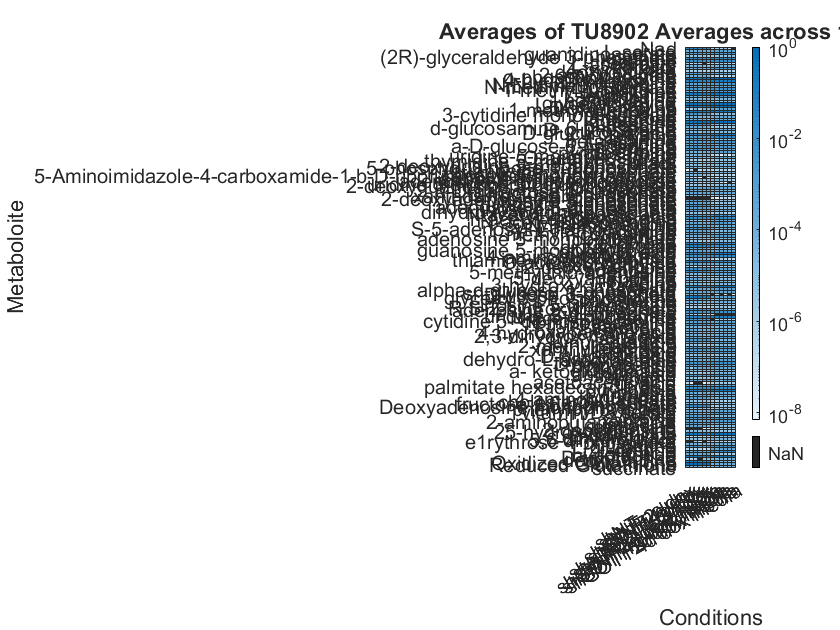

figure (15);
heatmap(all_conditions, metabolomics_TU8902_06(:,1),table2array(filtered_table_TU8902_06), 'ColorScaling', 'log');
title 'Averages of TU8902 Averages across 12 Conditions';
xlabel('Conditions');
ylabel('Metaboloite');

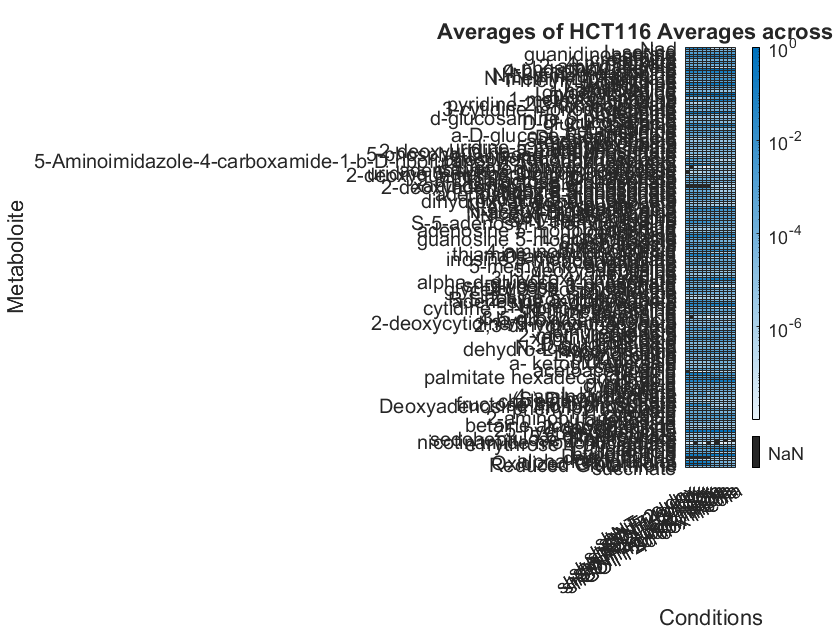


figure (16);
heatmap(all_conditions, metabolomics_HCT116_06(:,1),table2array(filtered_table_HCT116_06), 'ColorScaling', 'log');
title 'Averages of HCT116 Averages across 12 Conditions';
xlabel('Conditions');
ylabel('Metaboloite'); 